## Deliverable 1: Modelling and Kinematics

Autor: Ilyass Afkir

In this exercise we are looking at the **UR5 robot (Universal Robots)**, which shown in the figure down below. Frist the link frames will be drawn and then the DH table of parameters, including the offsets will be determined to match the configuration shown in the figure. Last but not least the corresponding SerialLink will be created and ploted at the configuration [0,0,0,0,0,0].

#### 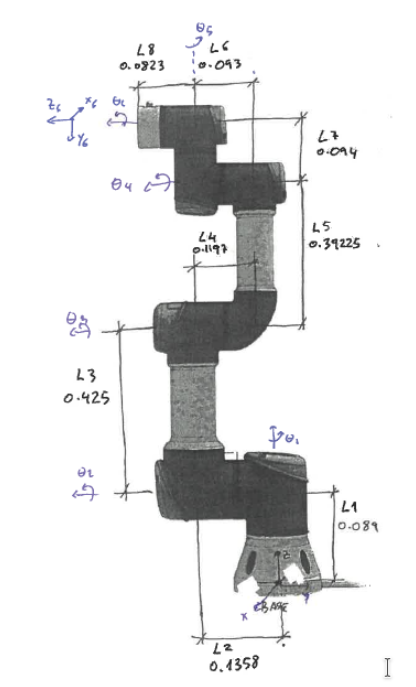

#### Link frames and DH-Parameters

The following figure shows the determinded DH-Parameters and frames including the offsets. **There is an error in the end effektor frame of the UR5 robot which is that y6-axis is not pointing in the right direction.**

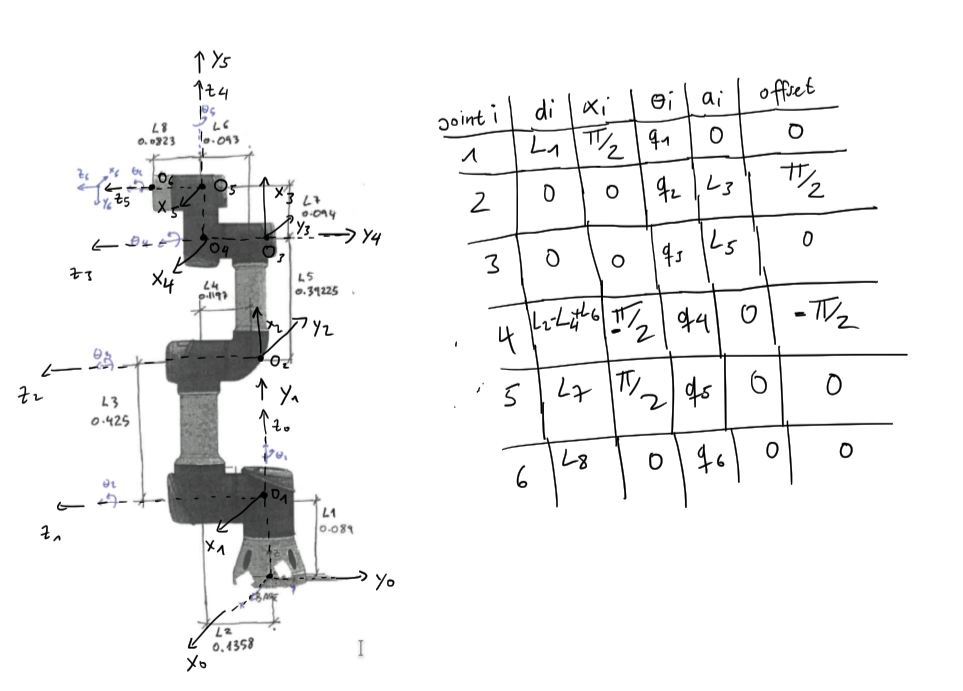

#### Creation of the corresponding SerialLink and plotting at configuration [0,0,0,0,0,0]

L(1) = Revolute('d', 0.089, 'alpha', pi/2);
L(2) = Revolute('a', 0.425, 'offset', pi/2);
L(3) = Revolute('a', 0.39225);
L(4) = Revolute('d', 0.1358-0.1197+0.093, 'alpha', -pi/2, 'offset', -pi/2);
L(5) = Revolute('d', 0.094, 'alpha', pi/2);
L(6) = Revolute('d', 0.0823);
L

 
L = 
Revolute(std):  theta=q1   d=0.089       a=0           alpha=1.571       offset=0          
Revolute(std):  theta=q2   d=0           a=0.425       alpha=0           offset=1.571      
Revolute(std):  theta=q3   d=0           a=0.3922      alpha=0           offset=0          
Revolute(std):  theta=q4   d=0.1091      a=0           alpha=-1.571      offset=-1.571     
Revolute(std):  theta=q5   d=0.094       a=0           alpha=1.571       offset=0          
Revolute(std):  theta=q6   d=0.0823      a=0           alpha=0           offset=0          


UR5 = SerialLink(L, 'name', 'UR5 robot')

 
UR5 = 
 
UR5 robot:: 6 axis, RRRRRR, stdDH, slowRNE                       
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|      0.089|          0|     1.5708|          0|
|  2|         q2|          0|      0.425|          0|     1.5708|
|  3|         q3|          0|    0.39225|          0|          0|
|  4|         q4|     0.1091|          0|    -1.5708|    -1.5708|
|  5|         q5|      0.094|          0|     1.5708|          0|
|  6|         q6|     0.0823|          0|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
 


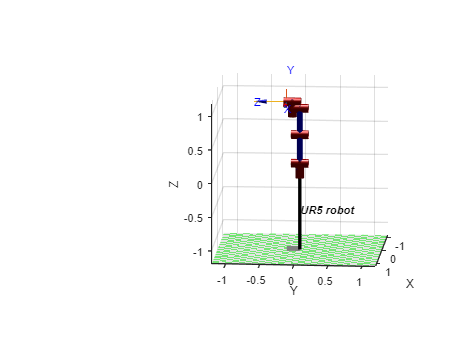

UR5.plot([0,0,0,0,0,0])
UR5.teach